# Actividad 3: Evaluación

Víctor Manuel Vázquez Morales A01736352

#### Ejercicio 1: 

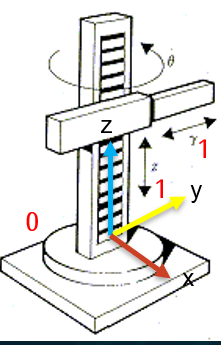

Para este primer ejercicio, notemos que se ven involucradas las siguientes variables: 

- theta 1: Que es el ángulo de la junta de revolución. 

- h: Altura de la junta de revolución. 

- l1: Longitud de la primera articulación

- l2: Longitud de la segunda articulación

%Declaración de variables simbólicas 
syms th1(t) l1
syms th2(t) l2
syms th3(t) l3
syms t
syms h

%configuracion del robot, 0 para junta rotacional y 1 para prismatica 
RP=[0 1 1]; 

%Vector de coordenadas articulares
Q = [th1,l1,l2]; 
disp('Coordenadas articulares'); 

Coordenadas articulares


pretty(Q);

(th1(t), l1, l2)




%vector de velocidad articulares
Qp = diff(Q,t); %se utiliza diff para derivadas cuya variable no depende de otras
disp('Velocidades articulares'); 

Velocidades articulares


pretty(Qp); 

/  d              \
| -- th1(t), 0, 0 |
\ dt              /




%numero de grado de libertad del robot
GDL = size(RP,2); %se coloca 2 para referirse a las columnas de la matriz 
GDL_str = num2str(GDL); %convertir numero a string


**Articulación 1: **

Para la primera articulación, únicamente hay una traslación en z de h, que vendria siendo la altura de la junta de revolución: 

%Articulacion 1 
%posicion de la junta 1 respecto a 0
P(:,:,1) = [0;
            0; 
            h];  

Posteriormente, la junta rota sobre el eje z: 

% Definir la matriz de rotación original R(:,:,1)
R(:,:,1) = [cos(th1) -sin(th1) 0; 
            sin(th1) cos(th1) 0; 
             0           0     1];

**Articulación 2: **

Convenientemente, ya tenemos el eje z alineado con la primera articulación prismática, por lo que procedemos a declarar el vector de traslación. En este caso, observemos que el movimiento de l1 se realiza sobre el eje z: 

%Articulación 2
%posicion de la junta 2 respecto a 1
P(:,:,2) = [0; 0; l1]; 


Ahora bien, para alinear el eje z con la siguiente articulación debemos rotar el sistema -90 grados sobre el eje x:  

%matriz de rotacion de articulacion 2
R(:,:,2) = [1 0 0; 
            0 0 1; 
            0 -1 0];   

**Articulación 3: **

Para este último caso, existe un desplazamiento de l2 sobre el eje z: 


%Articulación 3
%posicion de la junta 3 respecto a 2
P(:,:,3) = [0; 0; l2];  

Al ya no contar con una siguiente articulación, no es necesario rotar el sistema, por tanto, agregamos la matriz identidad a nuestra matriz de rotación: 

%matriz de rotacion de articulacion 3
R(:,:,3) = [1 0 0; 
            0 1 0; 
            0 0 1];  

**Cálculo de velocidades lineales y angulares: **


Vector_Zeros = zeros(1,3); 

%inicializamos matriz de transformacion homogenea local
A(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%inicializamos matriz de transformacion homogenea global ()
T(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

PO(:,:,GDL)= P(:,:,GDL); %vectores de posicion vistos desde el marco de referencia inercial

RO(:,:,GDL)= R(:,:,GDL); %matrices de rotacion distas desde el marco de referencia inercial

for i= 1: GDL
    i_str = num2str(i);
    %locales
    %disp(strcat('Matriz de transformacion local A',i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    %pretty (A(:,:,i));

    %globales
    try 
        T(:,:,i) = T(:,:,i-1)*A(:,:,i);
    catch 
        T(:,:,i) = A(:,:,i); %caso especifico cuando i= 1 nos marcaria error en try
    end 
    disp(strcat('Matriz de transformacion global T',i_str));
    T(:,:,i) = simplify(T(:,:,i));
    pretty(T(:,:,i));

    %obtenemos la matriz de rotacion RO y el vector de translacion PO de la
    %matriz de transformacion homogenea global T(:,:,GDL)

    RO(:,:,i) = T(1:3,1:3,i);
    PO(:,:,i) = T(1:3,4,i);
    pretty(RO(:,:,i));
    pretty(PO(:,:,i));
end 

Matriz de transformacion global T1


/ cos(th1(t)), -sin(th1(t)), 0, 0 \
|                                 |
| sin(th1(t)),  cos(th1(t)), 0, 0 |
|                                 |
|      0,            0,      1, h |
|                                 |
\      0,            0,      0, 1 /



/ cos(th1(t)), -sin(th1(t)), 0 \
|                              |
| sin(th1(t)),  cos(th1(t)), 0 |
|                              |
\      0,            0,      1 /



/ 0 \
|   |
| 0 |
|   |
\ h /



Matriz de transformacion global T2


/ cos(th1(t)),  0, -sin(th1(t)),    0   \
|                                       |
| sin(th1(t)),  0,  cos(th1(t)),    0   |
|                                       |
|      0,      -1,       0,      h + l1 |
|                                       |
\      0,       0,       0,         1   /



/ cos(th1(t)),  0, -sin(th1(t)) \
|                               |
| sin(th1(t)),  0,  cos(th1(t)) |
|                               |
\      0,      -1,       0      /



/    0   \
|        |
|    0   |
|        |
\ h + l1 /



Matriz de transformacion global T3


/ cos(th1(t)),  0, -sin(th1(t)), -l2 sin(th1(t)) \
|                                                |
| sin(th1(t)),  0,  cos(th1(t)),  l2 cos(th1(t)) |
|                                                |
|      0,      -1,       0,           h + l1     |
|                                                |
\      0,       0,       0,             1        /



/ cos(th1(t)),  0, -sin(th1(t)) \
|                               |
| sin(th1(t)),  0,  cos(th1(t)) |
|                               |
\      0,      -1,       0      /



/ -l2 sin(th1(t)) \
|                 |
|  l2 cos(th1(t)) |
|                 |
\      h + l1     /



%Calculamos el jacobiano lineal y angular de forma analitica
%inicializamod jacobianos analiticos (lineal y angular)
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k=1:GDL
    if((RP(k)==0)|(RP(k)==1))

        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1)); %Producto cruz
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1]; %No hay matriz de rotacion anterior, se imprime la matriz de identidad
        end
    else
        %articulaciones prismaticas
       try
           Jv_a(:,k)= RO(:,3,k-1);
       catch
           Jv_a(:,k)=[0,0,1];
       end
           Jw_a(:,k)=[0,0,0];
    end
end

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ -l2 cos(th1(t)), -l2 cos(th1(t)), 0 \
|                                     |
| -l2 sin(th1(t)), -l2 sin(th1(t)), 0 |
|                                     |
\        0,               0,        0 /



disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, 0, -sin(th1(t)) \
|                    |
| 0, 0,  cos(th1(t)) |
|                    |
\ 1, 1,       0      /




disp('Velocidad lineal obtenida mediante el Jacobiano Lineal');

Velocidad lineal obtenida mediante el Jacobiano Lineal


V=simplify (Jv_a*Qp');
pretty(V);

/     _________             \
|      d                    |
| -l2 -- th1(t) cos(th1(t)) |
|     dt                    |
|                           |
|     _________             |
|      d                    |
| -l2 -- th1(t) sin(th1(t)) |
|     dt                    |
|                           |
\             0             /



disp('Velocidad angular obtenido mediante el Jacobiano angular')

Velocidad angular obtenido mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
pretty(W);

/     0     \
|           |
|     0     |
|           |
| _________ |
|  d        |
| -- th1(t) |
\ dt        /



**Resultados: **

**Velocidad lineal: **

Es importante mencionar, que los resultaods que obtenemos para velocidad lineal no son los correctos, pues no es acorde al comportamiento del robot. Esto lo podemos notar especificamente por la velocida lineal en z: 

En nuestro caso, la velocidad en z es nula, sin embargo, al analisar nuestro robot podemos notar que en este eje existe el desplazamiento de una articulación, la cual hemos definido como l1, es decir, la velocidad que debimos haber obtenido debio haber sido la derivada de este desplazamiento. 

Por último, pese a que los resultados para los otros ejes son  incorrectos, es importante mencionar que si se ven afectados por senos y cosenos, esto debido a la rotación de la junta de revolución. 

**Velocidad angular: **

Si analizamos la composición de nuestro robot, observamos que contamos con dos juntas prismaticas y una rotacional de tipo de revolución. Notemos que esta articulación gira sobre el eje z que hemos definido a un ángulo de theta1. Es esta la razón por la que nuestro código arroja una velocidad angular con tal valor para el eje z, debido a la rotación de la junta ya mencionada. Ahora bien, ninguna otra junta rota sobre ningun otro eje, por lo que nuestras velocidades angulares para x y y son nulas. 